Testing on Random Adjusted Data

load hueCorrectionNetwork.mat

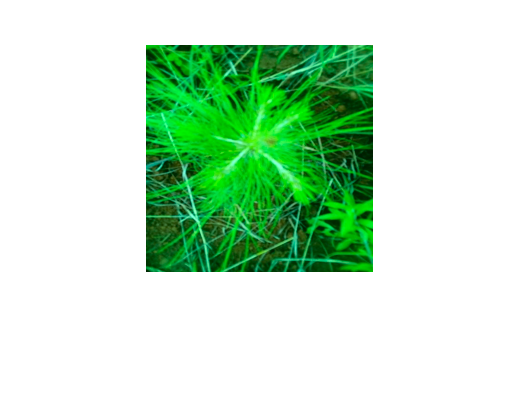

imds = imageDatastore('C:\Users\User\Google Drive\Greenstand\HueTest','FileExtensions','.tif');
outputPath = 'C:\Users\User\Google Drive\Greenstand\HueTestResults\';

for i = 1:length(imds.Files)
    img = readimage(imds,i);
    imshow(img);
    resizedImg = imresize(img, [227 227]);
    correction = predict(hueCorrectionNetwork, resizedImg);
    labImg = rgb2lab(img);
    labImg(:,:,2) =  labImg(:,:,2) + correction;
    rgbImage = lab2rgb(labImg);
     [~,name,~] = fileparts(imds.Files{i});
    writePath = strcat(outputPath,name,'.tif');
    imwrite(rgbImage,writePath,'tif');
    imshow(rgbImage);
end
 


 



 
  